# MAIN_EXP_3D_WAVEFORM_GRAPH: Generate figures of waveform estimation experiments

This script generates figures of resultes obtained by the interference waveform estimation with MAIN_EXP_3D_WAVEFORM_EST.

The results are stored in folder "./results" as follows:

-  ObsData: the observed data, adjusted for sampling and stripped of DC components

-  EstData: Estimated glass data.

-  rhat: the estimated refractive index distribution of the glass

-  theta: parameters required for the obtained interference waveform

Requirements: MATLAB R2020b

Copyright (c) 2022, Ruiki KOBAYASHI and Shogo MURAMATSU

All rights reserved.

Contact address: Shogo MURAMATSU,

   Faculty of Engineering, Niigata University,

   8050 2-no-cho Ikarashi, Nishi-ku,

   Niigata, 950-2181, JAPAN

    http://msiplab.eng.niigata-u.ac.jp/

dt = "2022-04-15-15-47";
targetdir = "./materials/exp_wave_" + dt;

%
wfigname = @(x) "./results/fig13"+string(char(96+x))+"rev.png";

agamma = 1.7;

## Load results


S = load(targetdir+"/glass_exp",'ObsData','gsaObs','rhat','EstData','gcost','xhat','theta');
ObsData = S.ObsData;
gsaObs = S.gsaObs;
EstData = S.EstData;
rhat = S.rhat;
theta = S.theta;

## Display results

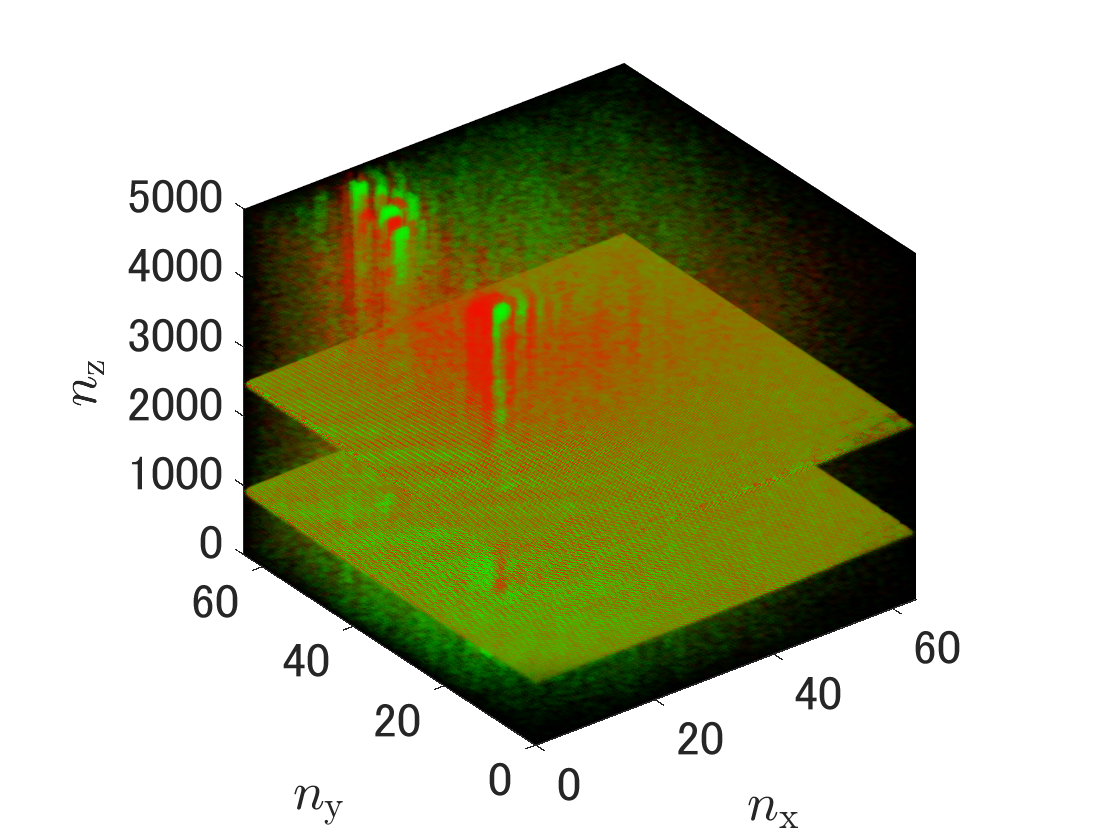

isubfig = 1;

% Observation
hfig = figure;
ObsData = ObsData - mean(ObsData,3);
voldata = ObsData/max(abs(ObsData(:)));
fcn_volviewer_(hfig,voldata,agamma);
drawnow
exportgraphics(hfig,wfigname(isubfig),"Resolution",300);

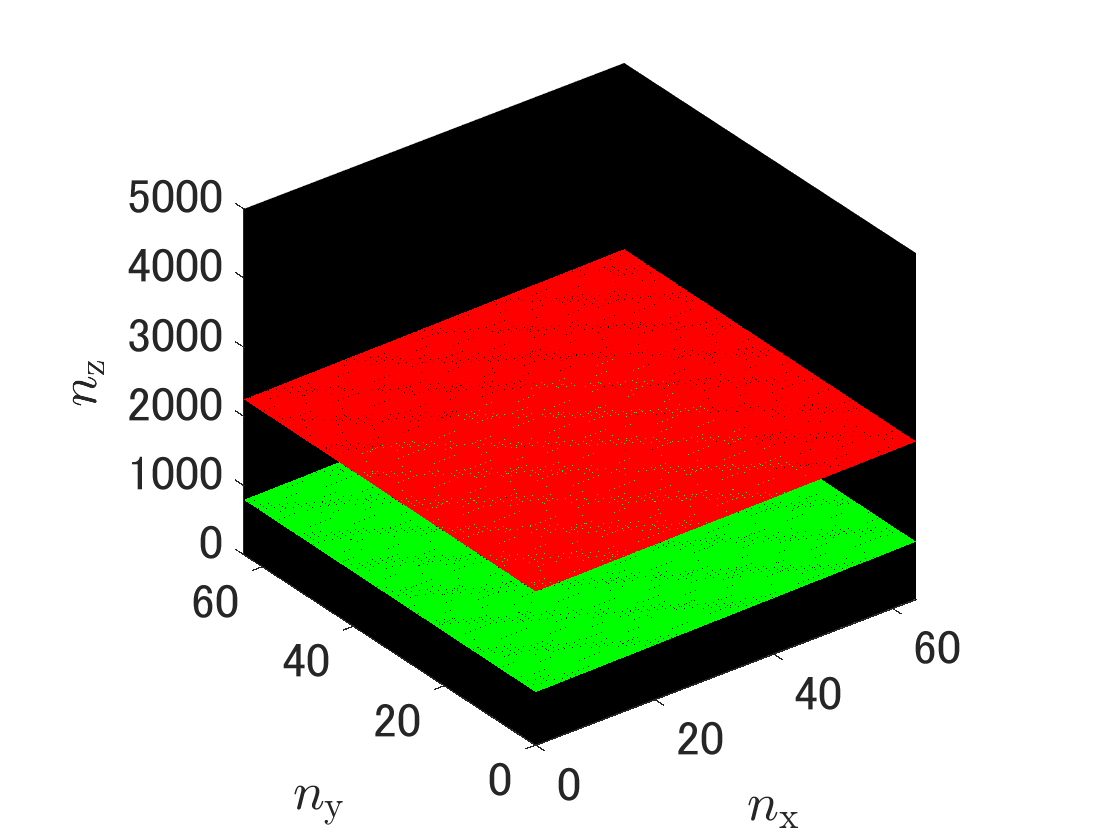

isubfig = isubfig+1;
close(hfig)

% Estimation
hfig = figure;
voldata = rhat;
fcn_volviewer_(hfig,voldata,agamma);
drawnow
exportgraphics(hfig,wfigname(isubfig),"Resolution",300);

isubfig = isubfig+1;
close(hfig)


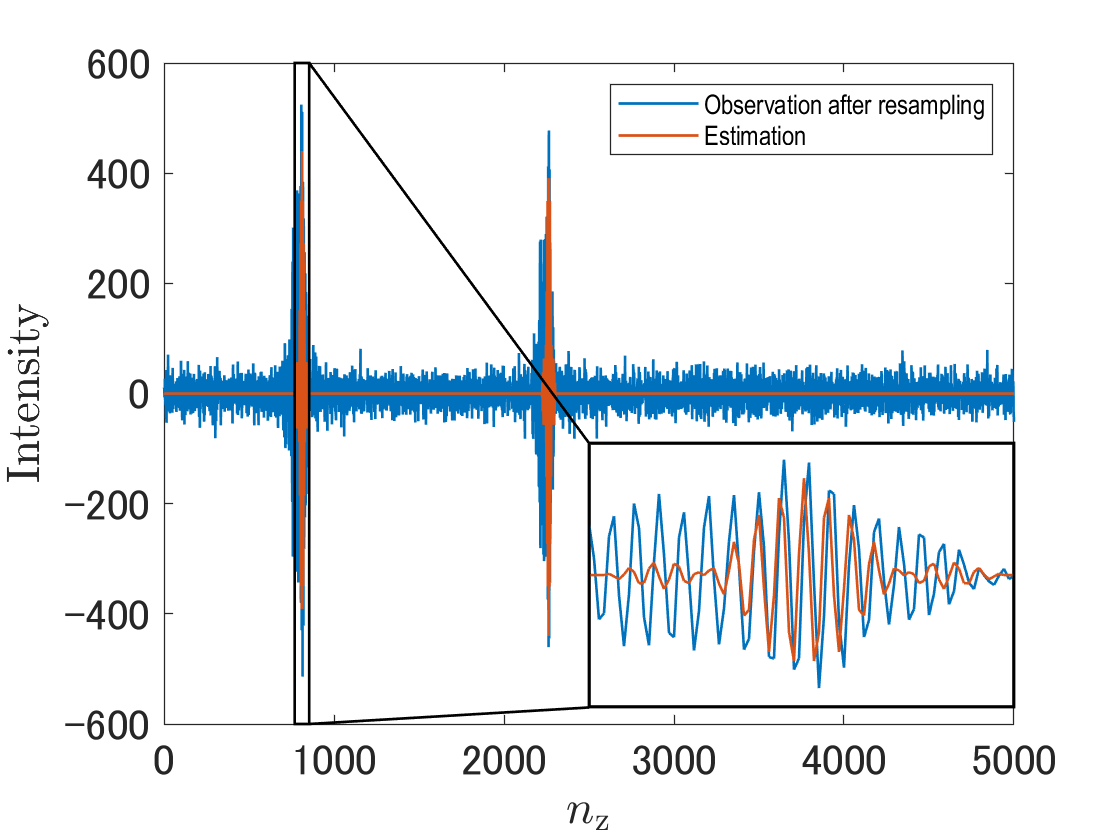

% Wave 
hfig = figure;
fcn_waveview_(hfig,gsaObs,EstData,...
    ["Observation after resampling","Estimation"],...
    "Intensity");
exportgraphics(hfig,wfigname(isubfig),"Resolution",300);

close(hfig)

function fcn_waveview_(hfig,v1,v2,signalnames,ylb)
    zline1 = squeeze(v1(floor(end/2),floor(end/2),:));
    hplt1 = plot(zline1);
    hplt1.LineWidth = 1;
    xlabel("$n_\mathrm{z}$","Interpreter","latex")
    ylabel(ylb,"Interpreter","latex")
    ymax = 600;
    ymin = -600;
    axis([0 size(v1,3) ymin ymax])
    ax = hplt1.Parent;
    %ax.DataAspectRatio = [81 1 1];
    ax.FontSize = 16;
    hold on
    %
    zline2 = squeeze(v2(floor(end/2),floor(end/2),:));
    hplt2 = plot(zline2);
    hplt2.LineWidth = 1;
    % Popout
    % - Reference
    % https://jp.mathworks.com/matlabcentral/fileexchange/30556-popout
    fgauss2 = fit((1:length(zline2)).',zline2(:),'gauss2');
    [b,idx] = min([fgauss2.b1,fgauss2.b2]);
    sgm = (idx==1)*sqrt(fgauss2.c1/2) + (idx==2)*sqrt(fgauss2.c2/2);
    xmin = floor(b-6*sgm);
    xmax = ceil(b+6*sgm);
    rectangle('Position',[xmin,ymin,xmax-xmin,ymax-ymin], 'linewidth', 1);
    line([xmax,2500],[ymax,-90],"Color","black","LineWidth",1) % TODO
    line([xmax,2500],[ymin,-570],"Color","black","LineWidth",1) % TODO
    %
    pos0 = ax.Position;
    axpp = copyobj(ax,hfig);
    ppleft = (pos0(1)+pos0(3)*(1/2));
    ppbottom =  (pos0(2)+pos0(4)*(1/40));
    ppwidth = pos0(3)/2;
    ppheight = pos0(4)*(4/10);
    axpp.Position = [ ppleft ppbottom ppwidth ppheight ];
    axpp.XLim = [xmin xmax];
    axpp.XLabel.String = "";
    axpp.YLabel.String = "";
    %axpp.DataAspectRatio = [1 10 1];
    axpp.XTick = [];
    axpp.YTick = [];
    axpp.LineWidth = 1;
    axpp.Color = [1 1 1];
    % Legend
    hlgnd = legend(ax,signalnames);
    hlgnd.FontSize = 10;
    hlgnd.FontName = "Arial Narrow";
    hold off
    %

end

function fcn_volviewer_(hfig,voldata,agamma)
    figure(hfig)
    bvol = zeros(size(voldata));
    gvol = voldata>0;
    rvol = voldata<0;
    cdata = cat(4,rvol,gvol,bvol);
    alpha  = (abs(voldata)/max(abs(voldata(:)))).^agamma;
    hvol = support.vol3d('CData',cdata,'Alpha',alpha);
    view(3)
    ax = hvol.parent;
    ax.XLim = [0 size(voldata,1)];
    ax.YLim = [0 size(voldata,2)];
    ax.ZLim = [0 size(voldata,3)];
    ax.Color = [0 0 0];
    ax.DataAspectRatio = [64 64 6000];
    ax.XTick = (0:2:6)*10;
    ax.YTick = (0:2:6)*10;
    ax.ZTick = (0:5)*1e3;
    ax.XLabel.String = "$n_\mathrm{x}$";
    ax.XLabel.Interpreter = "latex";
    ax.YLabel.String = "$n_\mathrm{y}$";
    ax.YLabel.Interpreter = "latex";
    ax.ZLabel.String = "$n_\mathrm{z}$";
    ax.ZLabel.Interpreter = "latex";
    ax.FontSize = 18;
end
